# Load resources

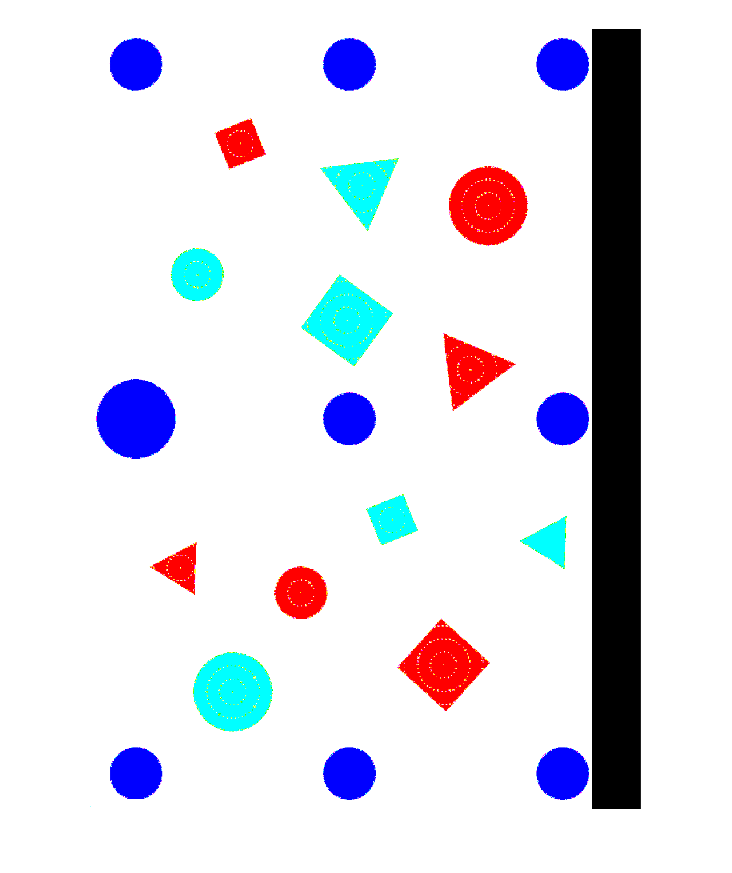

clear All; close all;
plainSpace = double(imread('EGB339 Pratice Sheet 1.jpg'));
start = double(imread("TestSheet1.jpg"));
goal = imread("TestSheet8.jpg");


% Zero the text part
plainImage = plainSpace;
plainImage(:,3015:end,:) = 0;
% plainImage = plainSpace(:,1:3015,:);  %double(plainspace(60:4619,129:2995,:));
imshow(plainImage)

## Run

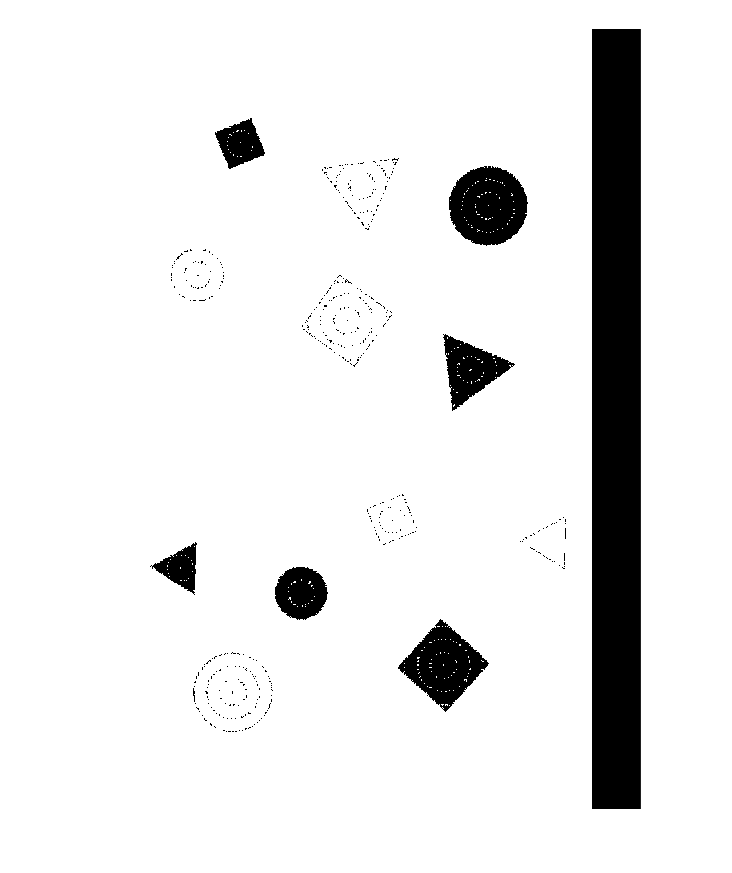


% Get colour plains
red = plainImage(:,:,1);
green = plainImage(:,:,2);
blue = plainImage(:,:,3);
imshow(blue)

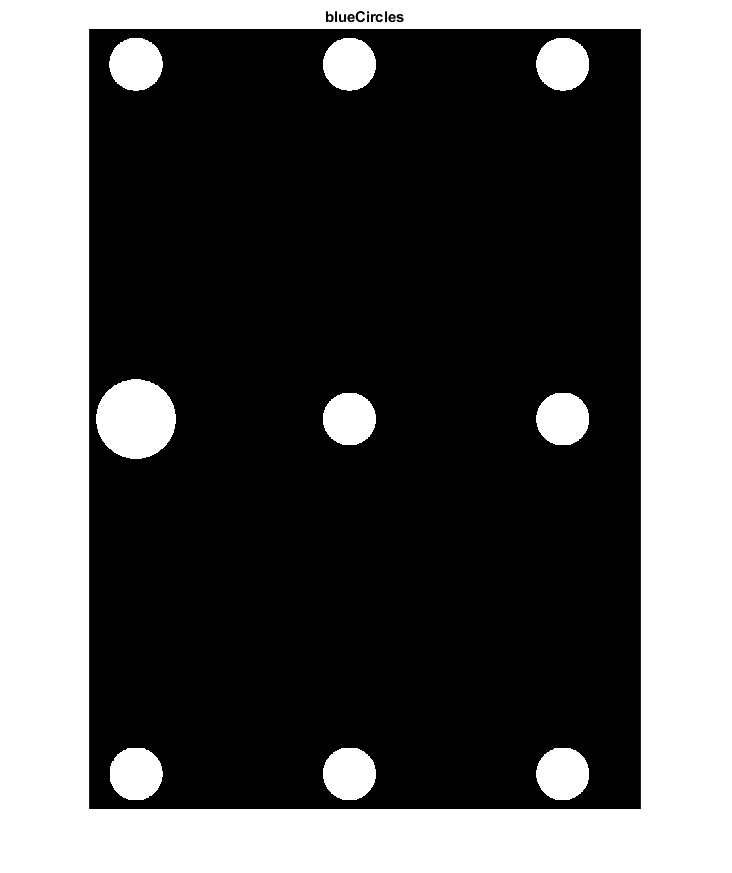


% Get blue circles
blueCircles = imclose(blue./(red+green+blue) > 0.5, ones(4,4));
figure; imshow(blueCircles); title('blueCircles');

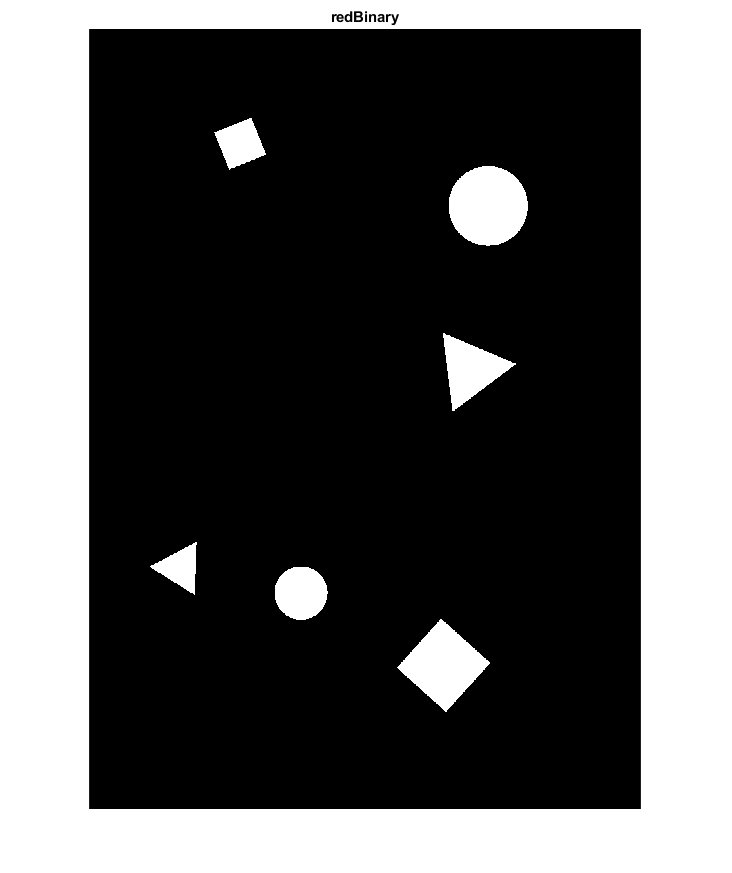


% get red shapes
% Old method to filter noise: redBinary = medfilt2(red./(red+green+blue) > 0.45, [3,3]);
redBinary = imclose(red./(red+green+blue) > 0.5, ones(4,4));
figure; imshow(redBinary); title('redBinary');

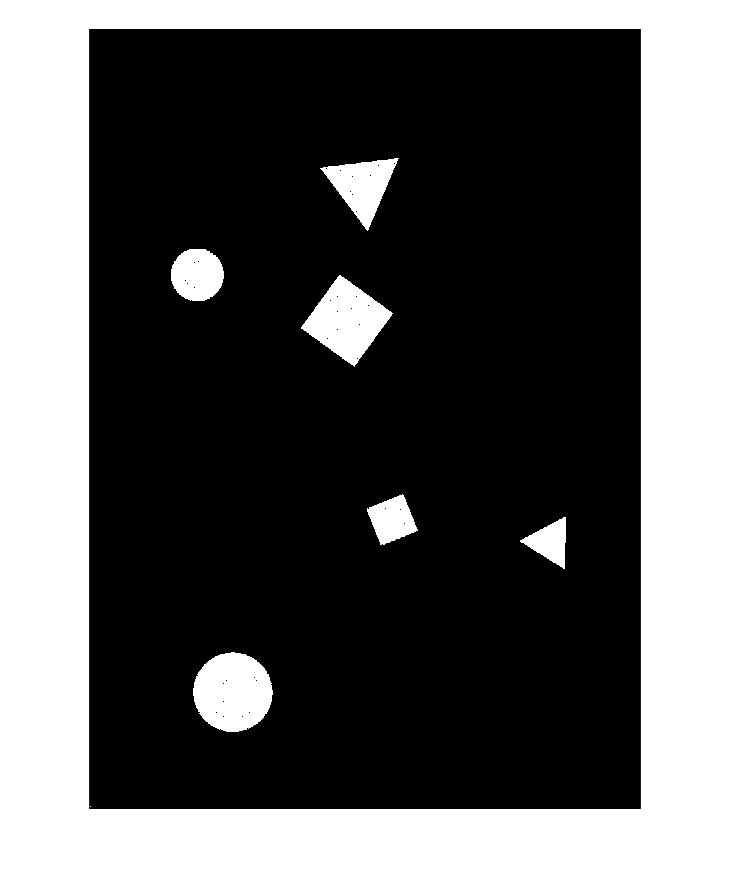


% Get green shapes
green = green./(red+green+blue) > 0.45;

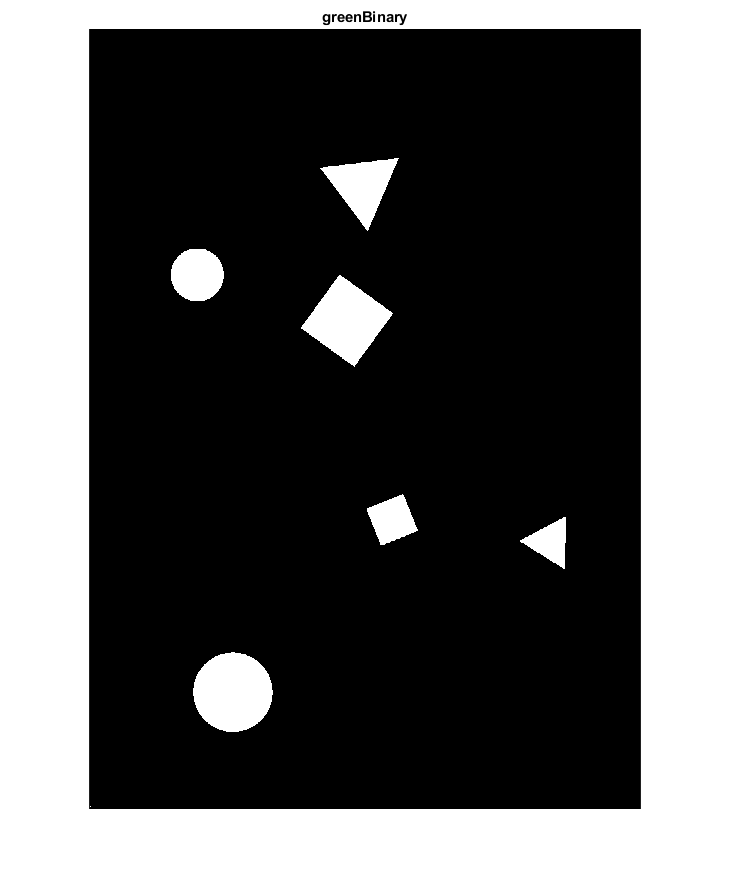

greenBinary = imclose(green, ones(5,5));
figure; imshow(greenBinary); title('greenBinary'); 

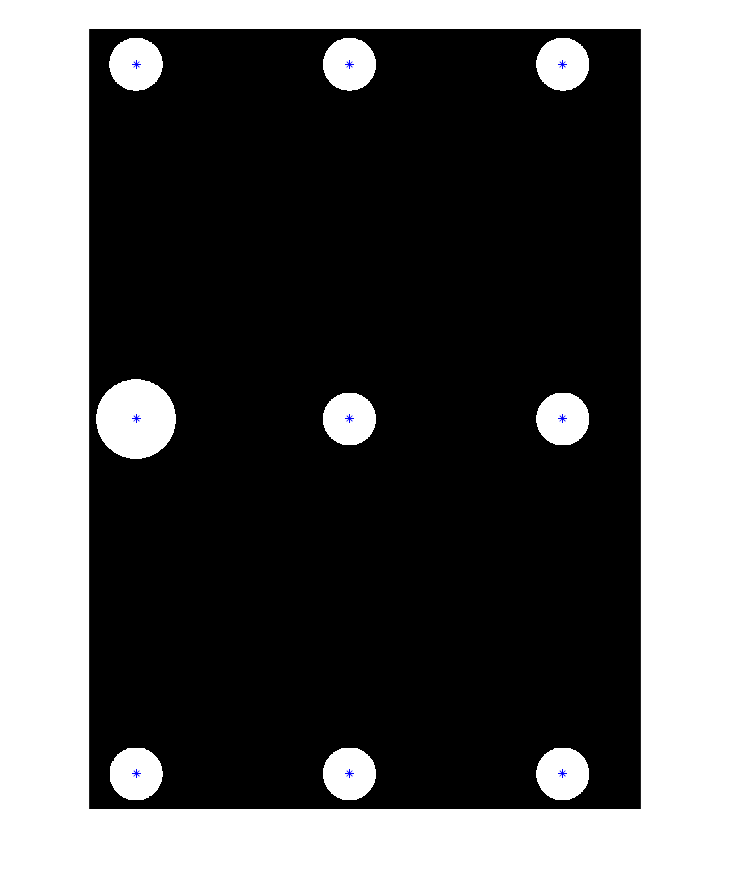


% Get data from sheet
% Get blue centroids
blueStats = regionprops("table",blueCircles,"Centroid","Area","Circularity");
imshow(blueCircles)
hold on
plot(blueStats.Centroid(:,1),blueStats.Centroid(:,2),'b*')
hold off

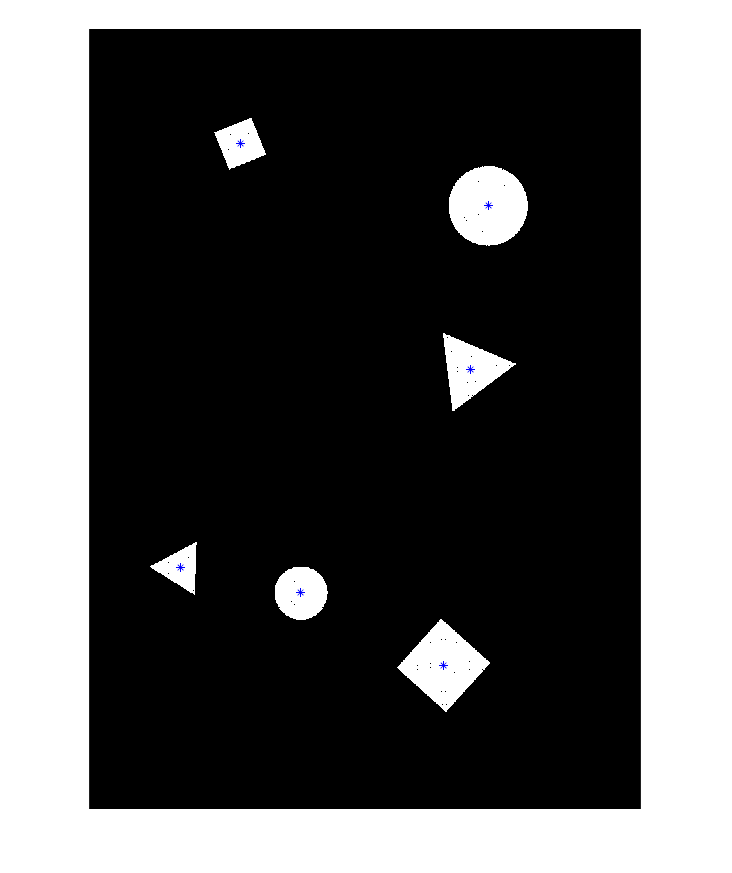


% Get red centroids
redStats = regionprops("table",redBinary,"Centroid","Area","Circularity");
imshow(redBinary)
hold on
plot(redStats.Centroid(:,1),redStats.Centroid(:,2),'b*')
hold off

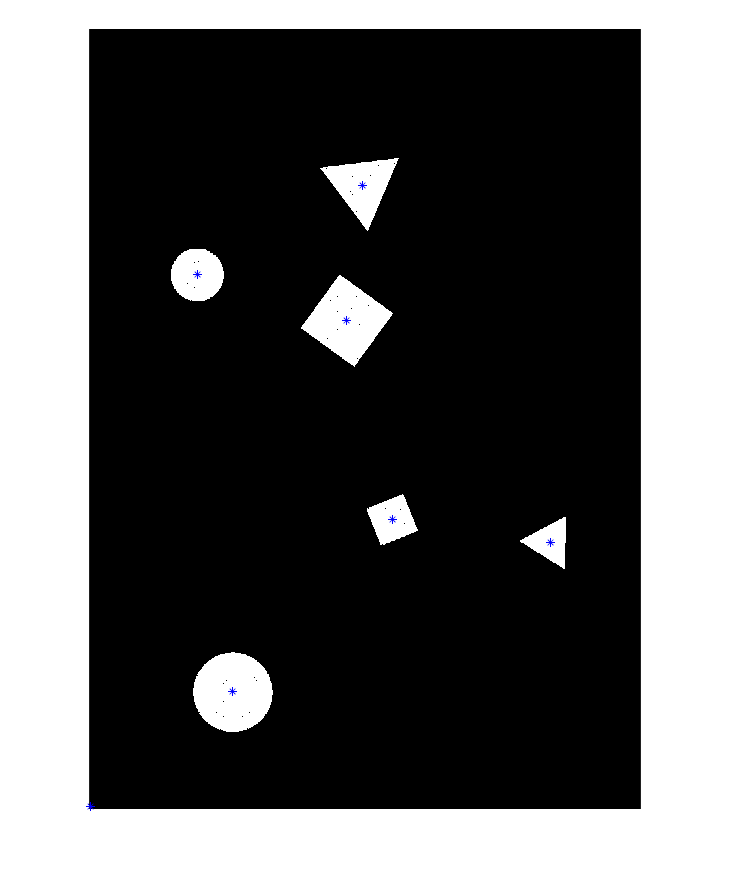


% Get green centroids
greenStats = regionprops("table",greenBinary,"Centroid","Area","Circularity");
imshow(greenBinary)
hold on
plot(greenStats.Centroid(:,1),greenStats.Centroid(:,2),'b*')
hold off

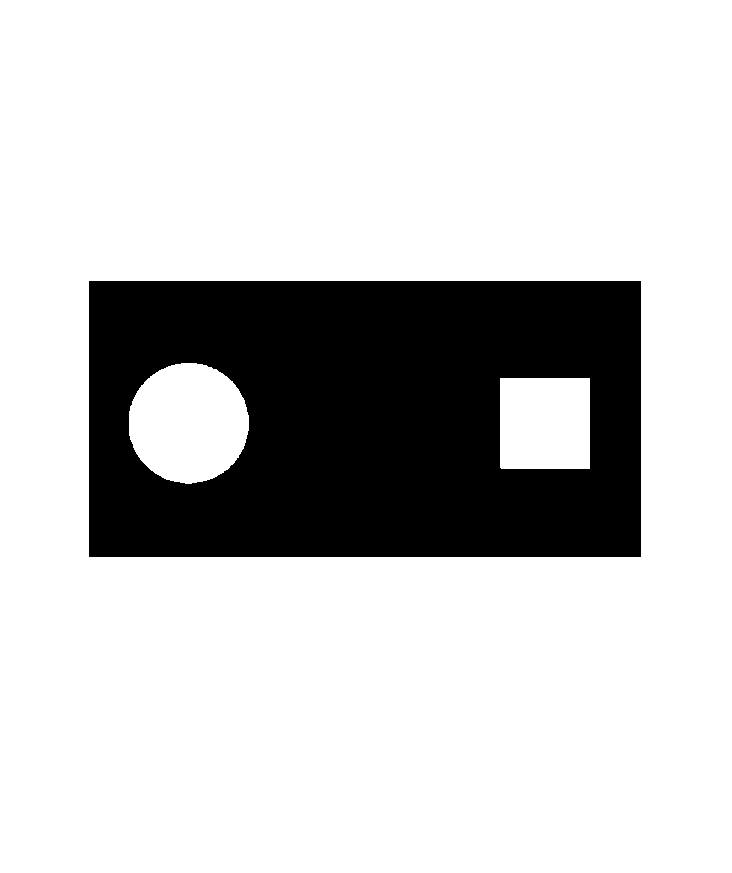


% Get start and end stats
% Get colour plains 
startRed = start(:,:,1);
startGreen = start(:,:,2);
startBlue = start(:,:,3);
startRed = startRed./(startRed+startGreen+startBlue) > 0.45;
imshow(startRed)

startprops = regionprops("table",startRed,"Centroid","Area","Circularity");

% Get cylinder data
% Load image with cylinders
% gotime = imread("EGB339 Pratice Sheet 2.jpg");
% gotime = double(gotime(60:4619,129:2995,:));
% ylinders = gotime-palinI; %theory: remove everything but cylinders
% Scylinders = regionprops("table",cylinders,"Centroid","Area","Circularity");